# Sistemas de ecuaciones diferenciales

## Campos de direcciones

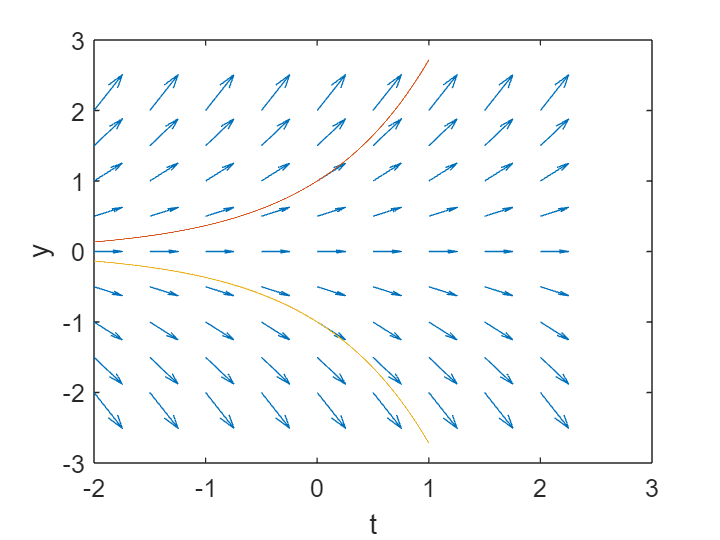

[t, y] = meshgrid(-2:0.5:2, -2:0.5:2);
dt = ones(9);
dy = y;
quiver(t, y, dt, dy)
xlabel('t')
ylabel('y')
hold on

t = -2:0.001:1;
y1 = exp(t);
y2 = -exp(t);
plot(t, y1, t, y2)
hold off


syms x(t) r
eqn = diff(x, t) == -(t/x);
xg = dsolve(eqn)

$$xg = \left(\begin{array}{c} \sqrt{C_{1}-t^{2}}\\ -\sqrt{C_{1}-t^{2}} \end{array}\right)$$

cond = x(0) == r;
xp = dsolve(eqn, cond)

$$xp = \left(\begin{array}{c} \sqrt{r^{2}-t^{2}}\\ -\sqrt{r^{2}-t^{2}} \end{array}\right)$$